clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+4, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 0;

tmax = 1000;
tspan = 0:0.1:tmax;

t_V = zeros(4, 1);  % CT0, CT6, CT12, CT18
for i = 1:4
    t_V(i) = 500 + 6 * (i - 1);
end

y = zeros(length(tspan), n_clock+4, 5);
parfor i = 1:4
    [~, y(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


% Clock knock out
K_BMAL1_V = par_scg(6);
par_scg(6) = 100000;
[~, y(:, :, 5)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(2));
par_scg(6) = K_BMAL1_V;

y = real(y);

% Smaller amplitude
y_sa = zeros(length(tspan), n_clock+4, 4);
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;

parfor i = 1:4
[~, y_sa(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end

par_clock(17) = vmax_bmal;
y_sa = real(y_sa);

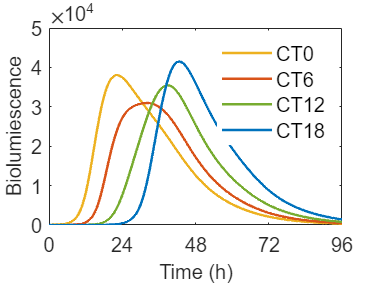

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = 1:4
    plot(tspan, y(:, n_clock+4, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

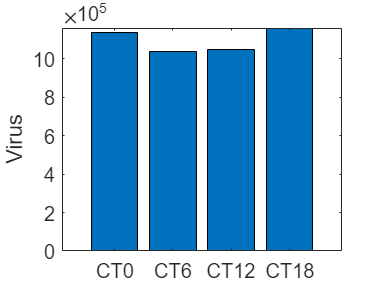

% calculate some related values of boiluminescence curve
biolu_tot = zeros(1, 5);
half_t = zeros(2, 5); % left, right

for i = 1:4
    B = y(:, n_clock+4, i);
    [peak_var, peak_idx] = max(B);
    B_left = B(1:peak_idx);
    B_right = B(peak_idx+1:end);

%     biolu_tot(i) = trapz(tspan(1:peak_idx), B_left) / trapz(tspan, B);
    biolu_tot(i) = trapz(tspan, B);
    [~, half_t(1, i)] = min(abs(B_left - peak_var / 2));
    [~, half_t(2, i)] = min(abs(B_right - peak_var / 2));

    % transfer to real time t
    half_t(1, i) = (half_t(1, i) - 1) ./ 10 - t_V(i);
    half_t(2, i) = (half_t(2, i) + peak_idx - 1) ./ 10 - t_V(i);
end

bar_name = categorical({'CT0', 'CT6', 'CT12', 'CT18'});
bar_name = reordercats(bar_name, {'CT0', 'CT6', 'CT12', 'CT18'});

bar(bar_name, biolu_tot(1:4)); ylabel('Virus');
set(gca,'Fontsize',12); box on;

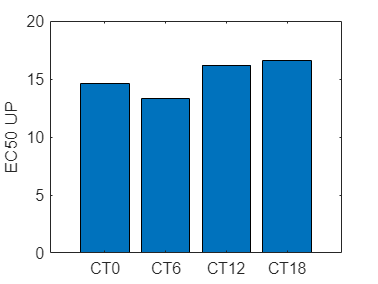

bar(bar_name, half_t(1, 1:4)); ylabel('EC50 UP');

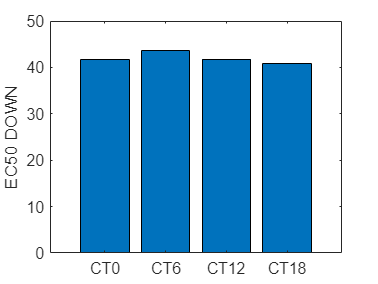

bar(bar_name, half_t(2, 1:4)); ylabel('EC50 DOWN');

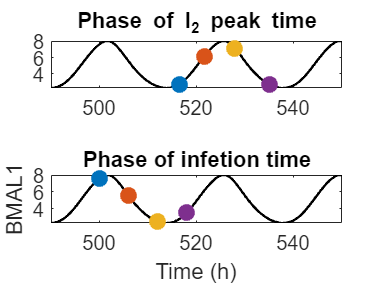

% Plot BMAL1 and phases of infection and peak time of I2
peak_idx_I2 = zeros(4, 1);    
for i = 1:4
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end
% half_t_real = zeros(4, 1);
% for i = 1:4
%     half_t_real(i) = half_t(1, i) + t_V(i);
% end
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560];
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, c, 'filled');
xlim([490 550]);
title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560];
scatter(t_V, y(t_V .* 10 + 1, 10, 1), sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('BMAL1');
title('Phase of infetion time');
hold off;

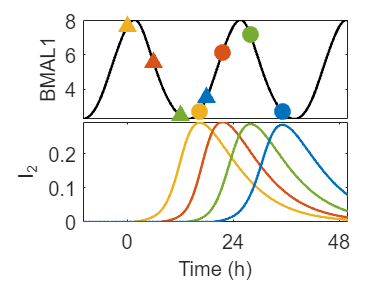

% Plot BMAL1 and phases of infection and peak time of I2
peak_idx_I2 = zeros(4, 1);    
for i = 1:4
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.58 0.7 0.35]);
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
sz = 100;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, color4, 'filled');
scatter(t_V, y(t_V .* 10 + 1, 10, 1), sz, color4, '^', 'filled');
xlim([490 550]);
xticks([]);
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.22 0.7 0.35]);
for i = 1:4
    plot(tspan, y(:, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

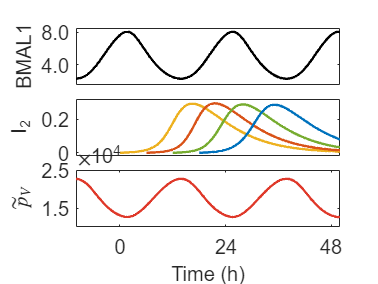

% Plot BMAL1 and phases of infection and peak time of I2
peak_idx_I2 = zeros(4, 1);    
for i = 1:4
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
xlim([490 550]);
xticks([]);
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
for i = 1:4
    plot(tspan((t_V(i)*10+1):end), y((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([]);
ylim([-0.02 0.32]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan, par_scg(4) .* par_scg(6) ./ (par_scg(6) + y(:, 10, 1)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
ylim([10000 25000]);
yticks([15000 25000]);
ylabel('$\tilde{p}_V$', 'interpreter', 'latex', 'Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;

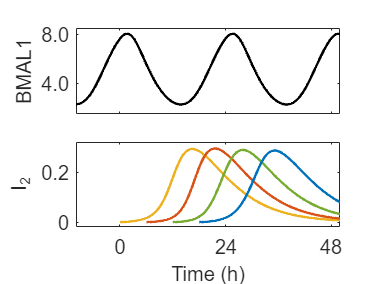

% Plot BMAL1 and phases of infection and peak time of I2

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 1.5);
xlim([490 550]);
xticks([500 524 548]);
xticklabels({});
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
for i = 1:4
    plot(tspan((t_V(i)*10+1):end), y((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
ylim([-0.02 0.32]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;

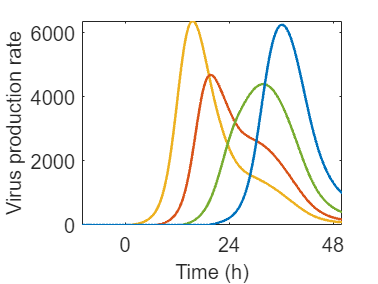

% plot K_BMAL1_V / (K_BMAL1_V + BMAL1) * p_V * I2
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = 1:4
    plot(tspan, par_scg(6)./(par_scg(6)+y(:, 10, i)).*par_scg(4).*y(:, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Virus production rate','Fontsize',12, 'FontName', 'Arial');
hold off;

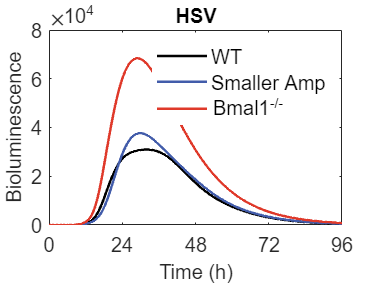

% Plot bioluminescence (B) clock ko
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, y(:, n_clock+4, 2), 'LineWidth', 1.5, 'Color', 'k');
plot(tspan, y_sa(:, n_clock+4, 2), 'LineWidth', 1.5, 'Color', '#425CAA');
plot(tspan, y(:, n_clock+4, 5), 'LineWidth', 1.5, 'Color', '#DF392A');
xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Bioluminescence','Fontsize',12, 'FontName', 'Arial');
title('HSV','Fontsize',12, 'FontName', 'Arial');
% legend('WT', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

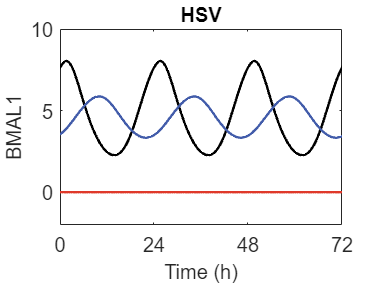

figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, y(:, 10, 2), 'LineWidth', 1.5, 'Color', 'k');
plot(tspan, y_sa(:, 10, 2), 'LineWidth', 1.5, 'Color', '#425CAA');
plot(tspan, zeros(10001, 1).*par_scg(4), 'LineWidth', 1.5, 'Color', '#DF392A');
xlim([500 572]);
ylim([-2 10]);
xticks(500:24:572);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('BMAL1', 'Fontsize',12, 'FontName', 'Arial');
title('HSV','Fontsize',12, 'FontName', 'Arial');
% legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

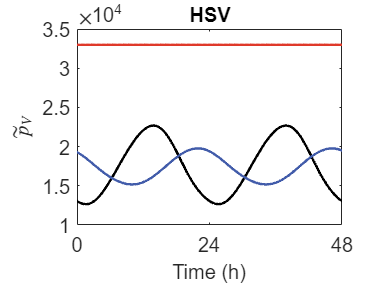

% clock disruption - clock evolution
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, par_scg(6)./(par_scg(6)+y(:, 10, 2)).*par_scg(4), 'LineWidth', 1.5, 'Color', 'k');
plot(tspan, par_scg(6)./(par_scg(6)+y_sa(:, 10, 2)).*par_scg(4), 'LineWidth', 1.5, 'Color', '#425CAA');
plot(tspan, par_scg(6)./(par_scg(6)+zeros(10001, 1)).*par_scg(4), 'LineWidth', 1.5, 'Color', '#DF392A');
xlim([500 548]);
xticks(500:24:548);
xticklabels({'0', '24', '48'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('$\tilde{p}_V$', 'interpreter','latex', 'Fontsize',12, 'FontName', 'Arial');
title('HSV','Fontsize',12, 'FontName', 'Arial');
% legend('WT', 'Smaller Amp', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

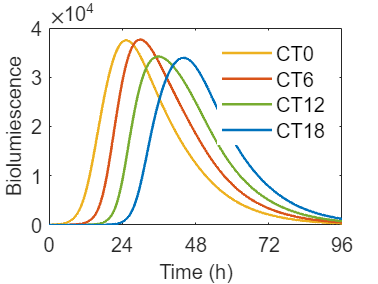

% Plot bioluminescence (B) of smaller amplitude
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = 1:4
    plot(tspan, y_sa(:, n_clock+4, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

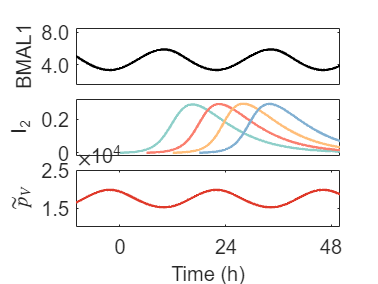

% Plot BMAL1 and phases of infection and peak time of I2

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(3, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.7 0.7 0.2]);
plot(tspan, y_sa(:, 10, 1), 'k', 'LineWidth', 1.5);
color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
xlim([490 550]);
xticks([]);
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.45 0.7 0.2]);
for i = 1:4
    plot(tspan((t_V(i)*10+1):end), y_sa((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([]);
ylim([-0.02 0.32]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(3, 1, 3); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.2]);
plot(tspan, par_scg(4) .* par_scg(6) ./ (par_scg(6) + y_sa(:, 10, 1)), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
ylim([10000 25000]);
yticks([15000 25000]);
ylabel('$\tilde{p}_V$', 'interpreter', 'latex', 'Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;

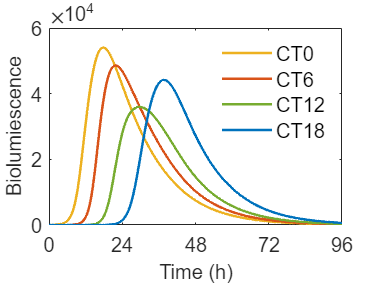

% change latent period (k_I)
y_k_I = zeros(length(tspan), n_clock+4, 4);
k_I = par_scg(2);
par_scg(2) = 0.5;

parfor i = 1:4
[~, y_k_I(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end

par_scg(2) = k_I;
y_k_I = real(y_k_I);

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = 1:4
    plot(tspan, y_k_I(:, n_clock+4, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',12, 'FontName', 'Arial');
legend('CT0', 'CT6', 'CT12', 'CT18', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

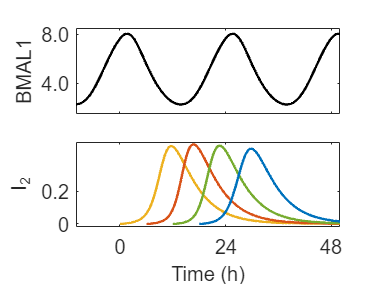


% Plot BMAL1 and phases of infection and peak time of I2
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y_k_I(:, 10, 1), 'k', 'LineWidth', 1.5);
xlim([490 550]);
xticks([500 524 548]);
xticklabels({});
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
for i = 1:4
    plot(tspan((t_V(i)*10+1):end), y_k_I((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
ylim([-0.02 0.5]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;

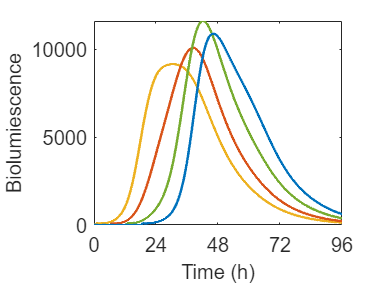

% change p_V
y_p_V = zeros(length(tspan), n_clock+4, 4);
p_V = par_scg(4);
par_scg(4) = 10000;

parfor i = 1:4
[~, y_p_V(:, :, i)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end

par_scg(4) = p_V;
y_p_V = real(y_p_V);

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = 1:4
    plot(tspan, y_p_V(:, n_clock+4, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',12, 'FontName', 'Arial');
% legend('CT0', 'CT6', 'CT12', 'CT18', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

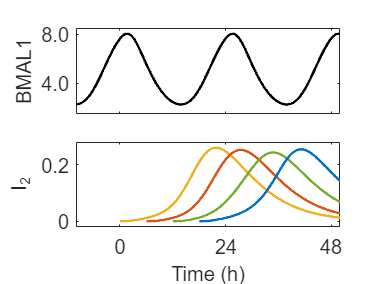


% Plot BMAL1 and phases of infection and peak time of I2
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y_p_V(:, 10, 1), 'k', 'LineWidth', 1.5);
xlim([490 550]);
xticks([500 524 548]);
xticklabels({});
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
for i = 1:4
    plot(tspan((t_V(i)*10+1):end), y_p_V((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
ylim([-0.02 0.28]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;